# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.15 能帮忙用matlab将这幅图画出来吗？或者您帮忙解答一下我在画图过程中的疑问？

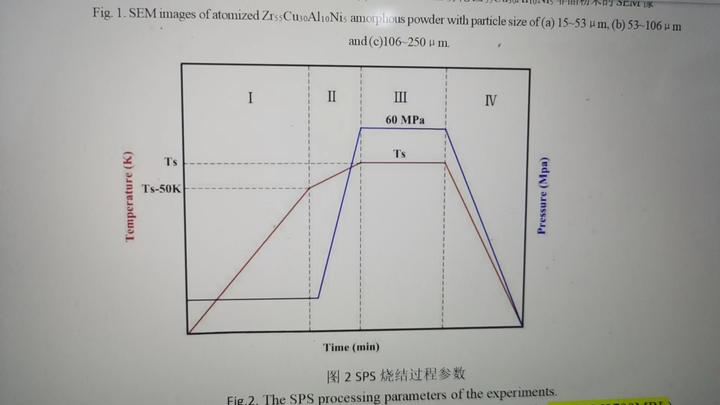

原问题：[https://www.zhihu.com/question/644279622/answer/3396277149](https://www.zhihu.com/question/644279622/answer/3396277149)

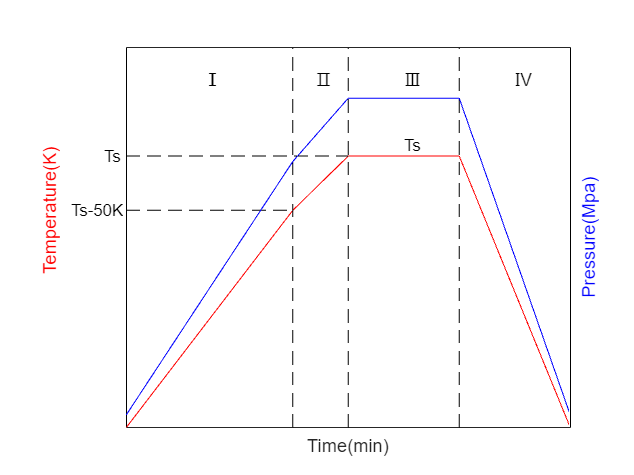

clear;clc;
xy = [0, 0; 15, 20; 20, 25; 30, 25; 40, 0];
% 时间数据
x = xy(:, 1);
% 温度数据
y = xy(:, 2);
% 画图
% 双坐标轴颜色
colororder({'k','k'})
% 左侧
yyaxis left
plot(x, y, 'r');
% y 轴范围
ylim([0, 35]);
% 几条虚线
hold on
for i = 2 : 4
    plot([x(i), x(i)], [0, 35], '--k')
end
for i = 2 : 3
    plot([x(1), x(i)], [y(i), y(i)], '--k')
end
hold off
% 隐藏刻度
set(gca, 'TickDir', 'none');
set(gca, 'XTickLabel', []);
set(gca, 'YTickLabel', []);
% set(gca, 'TickDir', 'none', 'XTickLabel', '', 'YTickLabel', '');
% 标签
xlabel('Time(min)');
ylabel('Temperature(K)', 'Position', [-6, 20], 'Color', 'r');
% 画图区域位置
set(gca, 'Position', [0.2, 0.1, 0.7, 0.8]);
% 几个文字标注
text(-5, y(2), 'Ts-50K');
text(-2, y(3), 'Ts');
text(7, 32, 'Ⅰ');
text(7, 32, 'Ⅰ');
text(17, 32, 'Ⅱ');
text(25, 32, 'Ⅲ');
text(35, 32, 'Ⅳ');
text(25, 26, 'Ts');
% 右侧
yyaxis right
% 类似画图
plot(x, y + 1, 'b');
% 类似设置
ylabel('Pressure(Mpa)', 'Color', 'b');
set(gca, 'TickDir', 'none');
set(gca, 'XTickLabel', []);
set(gca, 'YTickLabel', []);